close all;
clear;
Cell = readcell('Datasets\Task2\LetterClassification_GT.xlsx');

% Extract 
letters = Cell(4:41, 3);  
img_name = Cell(4:41, 2);

letters_array = cellfun(@char, letters, 'UniformOutput', false);
img_array = cellfun(@char, img_name, 'UniformOutput', false);

% Convert the cell array to a character array
%letter_string = cell2mat(letters);
%img_string= cell2mat(img_name);
% Initialize empty vectors for each group
vectorA = {};
vectorB = {};
vectorC = {};
vectorI = {};
vectorL = {};
vectorV = {};
vectorW = {};

% Iterate through each element of letters
for i = 1:length(letters_array)
    
    % Check the letter and group accordingly
    if isequal(letters_array(i), "A");
        vectorA{end+1} = img_array{i};
    elseif isequal(letters_array(i), "B");
       vectorB{end+1} = img_array{i};
    elseif isequal(letters_array{i}, "C")
        vectorC{end+1} = img_array{i};
    elseif isequal(letters_array{i}, "I")
        vectorI{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'L')
        vectorL{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'V')
        vectorV{end+1} = img_array{i};
    elseif isequal(letters_array{i}, 'W')
        vectorW{end+1} = img_array{i};
    end
end

% Expressão regular para extrair os números
expressao_regular = '(\d+)';

% Loop para extrair os números de cada string
for i = 1:length(vectorA)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorA{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecA{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorB)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorB{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecB{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorC)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorC{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecC{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorI)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorI{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecI{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorL)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorL{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecL{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorV)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorV{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecV{i} = str2double(numeros_encontrados{1}{1});
end
for i = 1:length(vectorW)
    % Encontra os números na string atual
    numeros_encontrados = regexp(vectorW{i}, expressao_regular, 'tokens');
    % Converte os números para formato numérico e armazena no array de números
    vecW{i} = str2double(numeros_encontrados{1}{1});
end

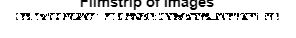


% Directory path
directory = 'Datasets\Task2\Images_with_BBs';

%%%%%%%%fazer isto para a imagem 1 chamada image com texto .name no inicio%%%%%%%%
% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.tif'));

% Loop through the list and read each image
images = cell(1, numel(fileList)); % Initialize cell array to store images

for i =1:numel(fileList)
    % Get the file name
    fileName = fullfile(directory, fileList(i).name);
    
    % Read the image
    image = imread(fileName);
    % Convert the image to grayscale
    grayImage = rgb2gray(image);
    
    % Create a bounding box around the coloured region eliminating the black background
    % Find the bounding box of the coloured region
    [rows, columns, ~] = find(grayImage ~= 0);
    % Get the bounding box
    boundingBox = [min(columns), min(rows), max(columns) - min(columns), max(rows) - min(rows)];

    % Crop the image using the bounding box
    croppedImage = imcrop(image, boundingBox);

    % Resize image to 64 x 64
    resizedImage = imresize(croppedImage, [64, 64]);
    
    % function preprocessing ( task1)
    graycroppedImage=preProcessing(resizedImage,64,64);
    
     % Define a threshold for black
    threshold = 0;

    % Create a binary image where black pixels are 1 and others are 0
    black_pixels = graycroppedImage == threshold;

    % Calculate the total number of pixels
    total_pixels = numel(graycroppedImage);

    % Calculate the number of black pixels
    num_black_pixels = sum(black_pixels(:));

    % if image is all black , igore preprocessing and aply simple mask
    if (num_black_pixels/total_pixels > 0.8) 
        graycroppedImage = rgb2gray(resizedImage);
        mask = false(size(graycroppedImage));
        mask(1:end,1:end) = true;
        img = activecontour(graycroppedImage, mask, 240);
        images{i} = img;
    else
        mask = false(size(graycroppedImage));
        mask(1:end,1:end) = true;
        img = activecontour(graycroppedImage, mask, 240);
        images{i} = img;
    end
end
figure;
montage(images, 'Size', [1, numel(fileList)]); title('Filmstrip of Images');

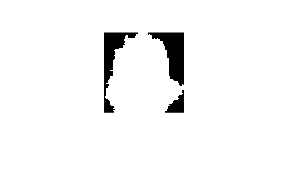


imshow(images{i});

for i = 1:length(images)
total = [0, 0, 0, 0, 0, 0, 0];
correlation = [0, 0, 0, 0, 0, 0, 0];
disp(i);
for j = 1:length(vecA)
    indice = vecA(j);
    if ~(i == indice{1})
            correlationA = normxcorr2(images{i}, images{indice{1}});
              [maxCorrA, maxIndexA] = max(abs(correlationA(:)));
            correlation(1) =  correlation(1) + maxCorrA;  %% acumula
            total(1) = total(1) + 1;  % n da para contar pelo length do vetor porque a imagem pode estar naquele conjunto

    end
end
% Calcula a média da correlação
correlation(1) = correlation(1) / total(1);
disp(correlation(1));

for j = 1:length(vecB)
    indice = vecB(j);
    if ~(i == indice{1})
            correlationB = normxcorr2(images{i}, images{indice{1}});
              [maxCorrB, maxIndexB] = max(abs(correlationB(:)));
            correlation(2) =  correlation(2) + maxCorrB;
            total(2) = total(2) + 1; 

    end
end
% Calcula a média da correlação
correlation(2) = correlation(2) / total(2);
disp(correlation(2));

for j = 1:length(vecC)
    indice = vecC(j);
    if ~(i == indice{1})
            correlationC = normxcorr2(images{i}, images{indice{1}});
              [maxCorrC, maxIndexC] = max(abs(correlationC(:)));
            correlation(3) =  correlation(3) + maxCorrC;
            total(3) = total(3) + 1;

    end
end
% Calcula a média da correlação
correlation(3) = correlation(3) / total(3);
disp(correlation(3));

for j = 1:length(vecI)
    indice = vecI(j);
    if ~(i == indice{1})
            correlationI = normxcorr2(images{i}, images{indice{1}});
              [maxCorrI, maxIndexI] = max(abs(correlationI(:)));
            correlation(4) =  correlation(4) + maxCorrI;
            total(4) = total(4) + 1;  

    end
end
% Calcula a média da correlação
correlation(4) = correlation(4) / total(4);
disp(correlation(4));

for j = 1:length(vecL)
    indice = vecL(j);
    if ~(i == indice{1})
            correlationL = normxcorr2(images{i}, images{indice{1}});
              [maxCorrL, maxIndexL] = max(abs(correlationL(:)));
            correlation(5) =  correlation(5) + maxCorrL;
            total(5) = total(5) + 1;  

    end
end
% Calcula a média da correlação
correlation(5) = correlation(5) / total(5);
disp(correlation(5));

for j = 1:length(vecV)
    indice = vecV(j);
    if ~(i == indice{1})
            correlationV = normxcorr2(images{i}, images{indice{1}});
              [maxCorrV, maxIndexV] = max(abs(correlationV(:)));
            correlation(6) =  correlation(6) + maxCorrV;
            total(6) = total(6) + 1;  

    end
end
% Calcula a média da correlação
correlation(6) = correlation(6) / total(6);
disp(correlation(6));

for j = 1:length(vecW)
    indice = vecW(j);
    if ~(i == indice{1})
            correlationW = normxcorr2(images{i}, images{indice{1}});
              [maxCorrW, maxIndexW] = max(abs(correlationW(:)));
            correlation(7) =  correlation(7) + maxCorrW;
            total(7) = total(7) + 1;  

    end
end
% Calcula a média da correlação
correlation(7) = correlation(7) / total(7);
disp(correlation(7));

[maxValue, maxPosition] = max(correlation);
if maxPosition == 1
    result{i} = 'A';
elseif maxPosition == 2
    result{i} = 'B';
elseif maxPosition == 3
    result{i} = 'C';
elseif maxPosition == 4
    result{i} = 'I';
elseif maxPosition == 5
    result{i} = 'L';
elseif maxPosition == 6
    result{i} = 'V';
elseif maxPosition == 7
    result{i} = 'W';
end
disp(result{i});
end

     1



    0.5568



    0.7034



    0.4836



    0.6009



    0.5107



    0.5104



    0.5337



B


     2



    0.6054



    0.5998



    0.5368



    0.6082



    0.6213



    0.5065



    0.5606



L


     3



    0.4255



    0.5360



    0.4201



    0.4306



    0.4203



    0.4158



    0.4259



B


     4



    0.3993



    0.4379



    0.4823



    0.4187



    0.4388



    0.4000



    0.3895



C


     5



    0.4597



    0.4626



    0.4211



    0.5043



    0.4007



    0.4900



    0.4984



I


     6



    0.6737



    0.5322



    0.5112



    0.5548



    0.4703



    0.4805



    0.5128



A


     7



    0.6653



    0.5383



    0.4664



    0.5481



    0.4438



    0.4791



    0.5042



A


     8



    0.5867



    0.5945



    0.4786



    0.5457



    0.4953



    0.6680



    0.5576



V


     9



    0.4887



    0.4373



    0.4871



    0.4512



    0.4379



    0.4475



    0.4220



A


    10



    0.5040



    0.5355



    0.5012



    0.5788



    0.4785



    0.5184



    0.5896



W


    11



    0.6041



    0.6042



    0.4963



    0.6844



    0.4941



    0.5059



    0.5563



I


    12



    0.7060



    0.7150



    0.7172



    0.6988



    0.6770



    0.7057



    0.7034



C


    13



    0.5991



    0.6008



    0.5406



    0.6367



    0.5284



    0.5527



    0.5869



I


    14



    0.8327



    0.7519



    0.8020



    0.7607



    0.7018



    0.7272



    0.7499



A


    15



    0.6111



    0.6824



    0.5186



    0.5833



    0.4483



    0.4888



    0.5213



B


    16



    0.6363



    0.4986



    0.4744



    0.4959



    0.4446



    0.4777



    0.4630



A


    17



    0.6130



    0.6538



    0.5388



    0.6205



    0.6261



    0.5346



    0.5768



B


    18



    0.4546



    0.4560



    0.3885



    0.4476



    0.3667



    0.4300



    0.4115



B


    19



    0.4376



    0.4639



    0.5878



    0.4399



    0.4889



    0.4402



    0.4209



C


    20



    0.5999



    0.6493



    0.5462



    0.6301



    0.5664



    0.5788



    0.5934



B


    21



    0.4807



    0.4853



    0.4892



    0.3803



    0.4539



    0.4296



    0.4227



C


    22



    0.5908



    0.6645



    0.4908



    0.5881



    0.5095



    0.5066



    0.5484



B


    23



    0.6028



    0.6526



    0.5234



    0.7090



    0.5106



    0.5241



    0.5980



I


    24



    0.4864



    0.4785



    0.4813



    0.5079



    0.5194



    0.4809



    0.4850



L


    25



    0.4476



    0.4274



    0.5877



    0.4337



    0.4607



    0.3993



    0.3949



C


    26



    0.6730



    0.6800



    0.5114



    0.7081



    0.5317



    0.5652



    0.6326



I


    27



    0.5403



    0.5545



    0.4740



    0.5857



    0.4502



    0.5551



    0.5223



I


    28



    0.6398



    0.6496



    0.5828



    0.6491



    0.6592



    0.5398



    0.5930



L


    29



    0.6491



    0.5795



    0.5480



    0.6539



    0.5338



    0.5074



    0.5529



I


    30



    0.5153



    0.5513



    0.5126



    0.5725



    0.4873



    0.5331



    0.6010



W


    31



    0.6214



    0.6518



    0.4607



    0.6584



    0.4528



    0.5491



    0.5580



I


    32



    0.6122



    0.5929



    0.5594



    0.5894



    0.5371



    0.5914



    0.5927



A


    33



    0.4985



    0.4918



    0.5156



    0.5123



    0.4813



    0.5180



    0.5160



V


    34



    0.6772



    0.6729



    0.5594



    0.6687



    0.5345



    0.5492



    0.6191



A


    35



    0.6101



    0.5538



    0.5393



    0.5205



    0.4707



    0.6241



    0.5357



V


    36



    0.3301



    0.3610



    0.3421



    0.3625



    0.3568



    0.3345



    0.3191



I


    37



    0.5258



    0.5704



    0.4858



    0.5741



    0.5010



    0.5698



    0.5096



I


    38



    0.6006



    0.6738



    0.5330



    0.5482



    0.4687



    0.4896



    0.5327



B



    tasserto = 0;
for i= 1:length(result)
    if isequal(result{i}, letters_array{i})
        tasserto = tasserto + 1;
    else
        fprintf("ERRADO imagem n %d ...resultado obtido = %s ...resultado esperado = %s\n", i, result{i}, letters_array{i});
    end
end

ERRADO imagem n 5 ...resultado obtido = I ...resultado esperado = W
ERRADO imagem n 9 ...resultado obtido = A ...resultado esperado = W
ERRADO imagem n 12 ...resultado obtido = C ...resultado esperado = L
ERRADO imagem n 13 ...resultado obtido = I ...resultado esperado = A
ERRADO imagem n 14 ...resultado obtido = A ...resultado esperado = C
ERRADO imagem n 17 ...resultado obtido = B ...resultado esperado = L
ERRADO imagem n 18 ...resultado obtido = B ...resultado esperado = I
ERRADO imagem n 21 ...resultado obtido = C ...resultado esperado = A
ERRADO imagem n 27 ...resultado obtido = I ...resultado esperado = V
ERRADO imagem n 29 ...resultado obtido = I ...resultado esperado = W
ERRADO imagem n 32 ...resultado obtido = A ...resultado esperado = V
ERRADO imagem n 34 ...resultado obtido = A ...resultado esperado = I
ERRADO imagem n 36 ...resultado obtido = I ...resultado esperado = W
ERRADO imagem n 37 ...resultado obtido = I ...resultado esperado = V


disp(tasserto);

    24





figure;
montage(images, 'Size', [1, numel(fileList)]); title('Filmstrip of Images');

% Compute the confusion matrix
confMat = confusionmat(letters_array, result);

% Display the confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


figure;
disp(confMat);

     6     0     0     0     0     0     0
     1     3     1     0     0     0     0
     0     0     3     0     1     0     0
     0     0     0     2     1     0     3
     0     0     1     0     3     0     1
     0     0     0     0     1     3     2
     1     0     0     0     1     0     4



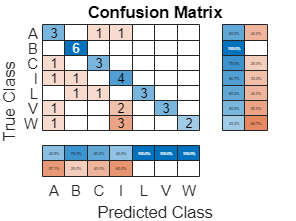


% Create a confusion chart
confChart = confusionchart(letters_array, result);

% Customize the confusion chart 
confChart.Title = 'Confusion Matrix';
confChart.RowSummary = 'row-normalized';
confChart.ColumnSummary = 'column-normalized';

function output=preProcessing(img,h,w)


    %YCbCr
    YCbCr=rgb2ycbcr(img);
    Cb=YCbCr(:,:,2);
    Cr=YCbCr(:,:,3); 
    %HSV
    HSV=rgb2hsv(img);

    [r,c,~]=find(Cr >= 140 & Cr <= 160 & Cb >= 95 & Cb <= 170 & HSV(:,:,1)<0.9);

    img_S_e = zeros(h, w);
    numind = size(r);

    for i=1:numind
        img_S_e(r(i),c(i)) = 1;
    end

    [L,~]=bwlabel(img_S_e);

    s=regionprops(L,'PixelIdxList','Area','BoundingBox','Centroid');

    idx=[s.Area]>=5000;
    if(find(idx==1))
        idx_to_keep = [s.Area] >= 5000;
    else
        idx_to_keep = [s.Area] >= 2000;
    end


    skin_px = zeros(h, w);
    for i = 1:size(idx_to_keep,2)
        if(idx_to_keep(i)==1)
            [r,c,~] = find(L==i);
            numind = size(r,1);
            for k=1:numind
                skin_px(r(k),c(k)) = 1;
            end
        end
    end


    output=skin_px;
end


